fid = fopen('celcom.trs','r');
dec2hex(fread(fid,1,'uint8'))

ans = '41'

dec2hex(fread(fid,1,'uint8'),2)

ans = '04'

m = [];
for i = 1:4
    m =[dec2hex(fread(fid,1,'uint8'),2) m];
end
m

m = '00000022'

% dec2hex(fread(fid,1,'uint32','l'),8)
% dec2hex(fread(fid,1,'integer*8','l'),8)
dec2hex(fread(fid,1,'uint8'))

ans = '42'

dec2hex(fread(fid,1,'uint8'))

ans = '4'

dec2hex(fread(fid,1,'uint32','l'),8)

ans = '0007A122'

fclose(fid);

for i = 1:0
    disp(i)
end

trs_info = get_trs_info('celcom.trs');

ans = 2×320 char array
    '0BEFBED807124DEA00F0FFFEEF8DEF3000F00000F0001111011AFFF30FFF0FFFFFFFF0FEFEEF8EFF410101000FFFEEFEEFEEF8EF04110010FFEEFFFFF01011B000400FF0FFFEEFFEFFF0FFF9EFF300FF0FFFEFFFE0001000AF115211010FFEEFFDFFF0FFFAF004100F0FFEEDEEBEEEFDDE8CEE2000010FFEDDDBEEDFDDE9DFF3100010FFEEEECFFF0FFFAFFF310101100FFFFDFFF0FFFAEFF300001100FFFFDF'
    '4D925C24D4B2A69D61CBB466E1CFF36503E77383E147E77EA32F9FFD48A21A8B7488104D10A0814A30E0B7B31450F8CEF8AE3C389EB2D836E9DE200FB42A3642FDAE1C938128C129B8767ABA9CEDE1CD8F63D3ADD466A663BB9E7870B2894BF246488DC88506B2881C6C0F0E21E5400CD5EE37040452DD72CCA834E2EC46A3803EC929EBB7871142D55CC4EC32C1E9067AB6558A6951645411F8AB83AAD55414'

trs_info = trs2mat('celcom.trs');

data_size = 16

m = {'ab';'cd';'ef'}

m = 3×1 cell array
    'ab'
    'cd'
    'ef'


reshape(m,1,[])

ans = 1×3 cell array
    'ab'    'cd'    'ef'


n = cell(3,1)

n = 3×1 cell array
    []
    []
    []


n(1,1) = {'ab'}

n = 3×1 cell array
    'ab'
    []
    []


n(2,1) = {'cd'}

n = 3×1 cell array
    'ab'
    'cd'
    []


n(3,1) = {'ef'}

n = 3×1 cell array
    'ab'
    'cd'
    'ef'


n = reshape(n,1,[])

n = 1×3 cell array
    'ab'    'cd'    'ef'


n = cat(2,n{:})

n = 'abcdef'

x = 1:0.01:pi

x =     1.0000    1.0100    1.0200    1.0300    1.0400    1.0500    1.0600    1.0700    1.0800    1.0900    1.1000    1.1100    1.1200    1.1300    1.1400    1.1500    1.1600    1.1700    1.1800    1.1900    1.2000    1.2100    1.2200    1.2300    1.2400    1.2500    1.2600    1.2700    1.2800    1.2900    1.3000    1.3100    1.3200    1.3300    1.3400    1.3500    1.3600    1.3700    1.3800    1.3900    1.4000    1.4100    1.4200    1.4300    1.4400    1.4500    1.4600    1.4700    1.4800    1.4900


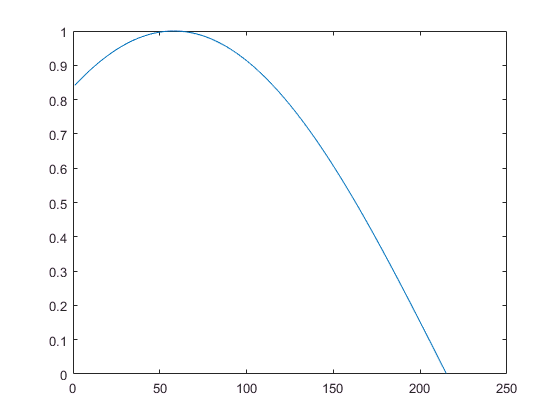

plot(sin(x))

m1 = '04BDE9F2B5ECD2840D741B224AD6E9AD'

m1 = '04BDE9F2B5ECD2840D741B224AD6E9AD'

m2 = reshape(m1,2,[])'

m2 = 16×2 char array
    '04'
    'BD'
    'E9'
    'F2'
    'B5'
    'EC'
    'D2'
    '84'
    '0D'
    '74'
    '1B'
    '22'
    '4A'
    'D6'
    'E9'
    'AD'

m2(:,3)=zeros(16,1)

m2 = 16×3 char array
    '04 '
    'BD '
    'E9 '
    'F2 '
    'B5 '
    'EC '
    'D2 '
    '84 '
    '0D '
    '74 '
    '1B '
    '22 '
    '4A '
    'D6 '
    'E9 '
    'AD '

m2 = reshape(m2',1,[])

m2 = '04 BD E9 F2 B5 EC D2 84 0D 74 1B 22 4A D6 E9 AD '